# Cluster analysis

- Different outlier removal techniques

- Clustergram

- Evalcluster

- Createns/Knn-search

load HCVEgyptData.mat
disp(HCV)

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

class(HCV)

ans = 'table'

size(HCV)

ans =         1385          29


sum(sum(ismissing(HCV)))

ans = 0

HCV_array=table2array(HCV)

HCV_array =           56           1          35           2           1           1           1           2           2           2        7425     4248807          14      112132          99          84          52         109          81           5           5           5      655330      634536      288194           5           5          13           2
          46           1          29           1           2           2           1           2           2           1       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085           4           2
          57           1          33           2           2           2           2           1           1           1        4178     4621191          12      151522         113          49          95         107         116           5           5           5      571148      661346  

### Testing different outlier removal techniques

size(rmoutliers(HCV_array)) % median

ans =      9    29


size(rmoutliers(HCV_array,'mean'))

ans =         1381          29


size(rmoutliers(HCV_array,'movmedian',5))

ans =     15    29


size(rmoutliers(HCV_array,'movmean',5))

ans =         1385          29


size(rmoutliers(HCV_array,'grubbs'))

ans =         1384          29


size(rmoutliers(HCV_array,'gesd'))

ans =         1384          29



% Only continuous variables
size(rmoutliers(HCV_array(:,[1,3:11,27])))

ans =     12    11


size(rmoutliers(HCV_array(:,[1,3:11,27]),'mean'))

ans =         1385          11


size(rmoutliers(HCV_array(:,[1,3:11,27]),'movmean',5))

ans =         1385          11


size(rmoutliers(HCV_array(:,[1,3:11,27]),'movmedian',5))

ans =     85    11


size(rmoutliers(HCV_array(:,[1,3:11,27]),'grubbs'))

ans =         1385          11


size(rmoutliers(HCV_array(:,[1,3:11,27]),'gesd'))

ans =         1385          11


### Clustergram for whole data vs first 100 observations (4 stages)

a=rmoutliers(HCV_array,'mean')

a =           46           1          29           1           2           2           1           2           2           1       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085           4           2
          49           2          33           1           2           1           2           1           2           1        6490     4794631          10      146457          43          64         109          80          88          48          77          33     1041941      449939      585688      744463      582301          10           3
          58           2          22           2           2           2           1           2           2           1       11785     3882456          15      131228          66         104         121          96          65          73         114          29     1157452     1086852          

b=array2table(a,'VariableNames',HCV.Properties.VariableNames())

b = 1381×29 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____  

HCV_stage=b.Baselinehistologicalstaging;
col_names2=b.Properties.VariableNames(1:27);

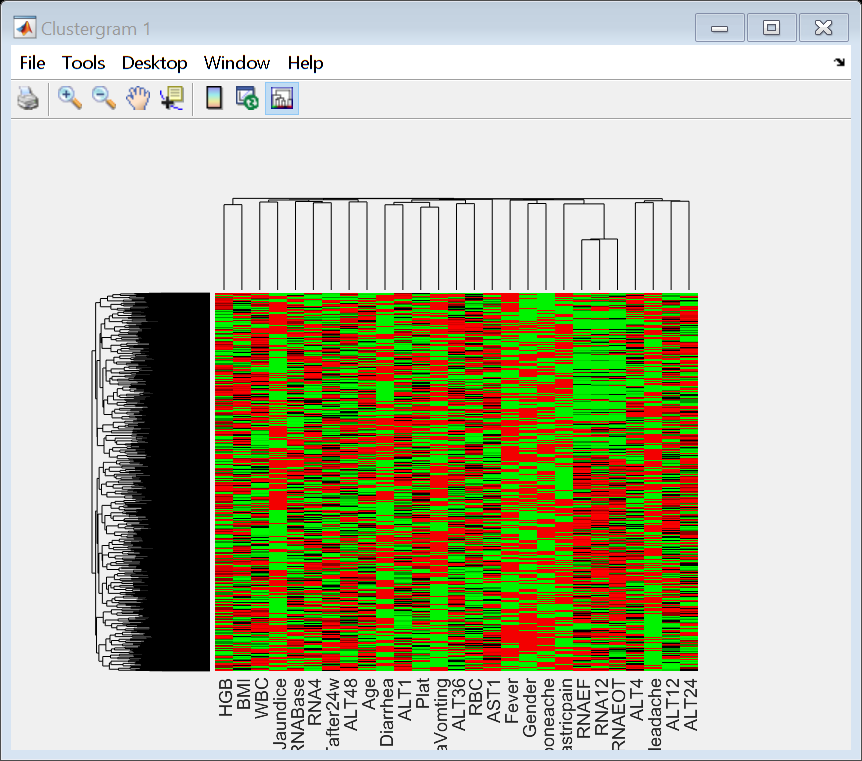

Clustergram object with 1381 rows of nodes and 27 columns of nodes.



hcg1=clustergram(a(:,1:27),...
    'RowLabels',HCV_stage,....
    'ColumnLabels',col_names2,...
    'Standardize','column',...
    'RowPdist','correlation',...
    'ColumnPdist','correlation')

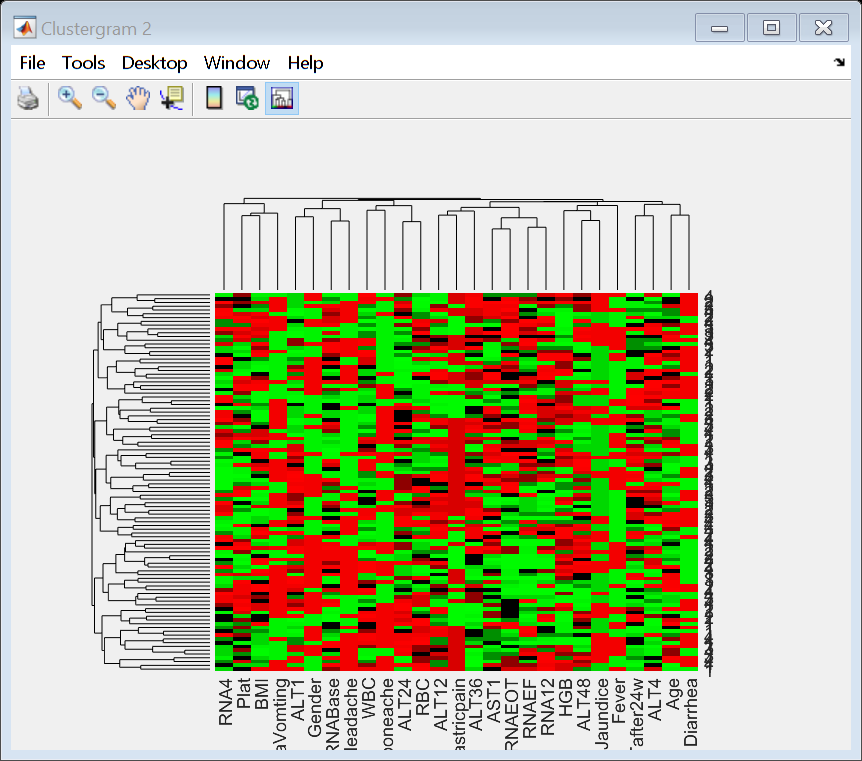

Clustergram object with 100 rows of nodes and 27 columns of nodes.



hcg2=clustergram(a(1:100,1:27),...
    'RowLabels',HCV_stage(1:100,1),....
    'ColumnLabels',col_names2,...
    'Standardize','column',...
    'RowPdist','correlation',...
    'ColumnPdist','correlation')

### Clustergram for 2 stages only

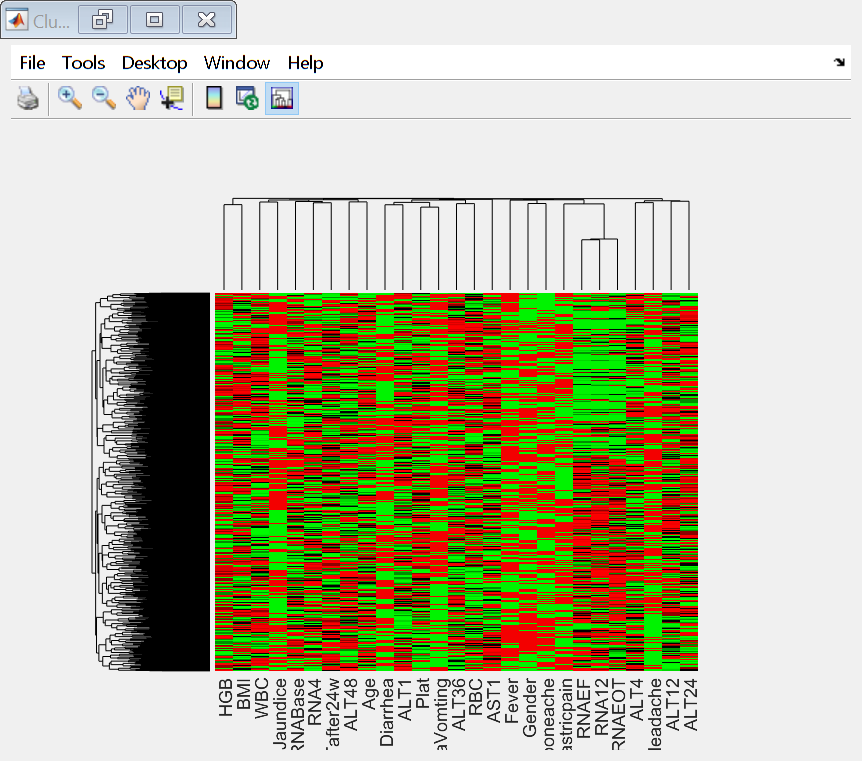

Clustergram object with 1381 rows of nodes and 27 columns of nodes.



for i=1:1381
    if b.Baselinehistologicalstaging>2
        stage(i,1)=2;
    else
        stage(i,1)=1;
    end
end
hcg3=clustergram(a(:,1:27),...
    'RowLabels',stage(:,1),....
    'ColumnLabels',col_names2,...
    'Standardize','column',...
    'RowPdist','correlation',...
    'ColumnPdist','correlation')

rng('default');  % For reproducibility
eva = evalclusters(a(:,1:27),'kmeans','silhouette','Distance','correlation',"KList",[1:10])

eva =   SilhouetteEvaluation with properties:

    NumObservations: 1381
         InspectedK: [1 2 3 4 5 6 7 8 9 10]
    CriterionValues: [NaN 0.3322 0.3413 0.3336 0.3450 0.3507 0.3376 0.3328 0.3274 0.3379]
           OptimalK: 6


x=a(:,1:27);
y=categorical(HCV_stage);
[Xtrain,Ytrain,Xtest,Ytest]=trainTestSplit(x,y,0.6);
Mdl=createns(Xtrain)

Mdl =   ExhaustiveSearcher with properties:

         Distance: 'euclidean'
    DistParameter: []
                X: [829×27 double]


idx=knnsearch(Mdl,Xtest,'K',2)

pred =    697   607
   603   386
   337    69
   344   188
   341    56
   137   134
   353   254
   411   104
   350   426
    78   726


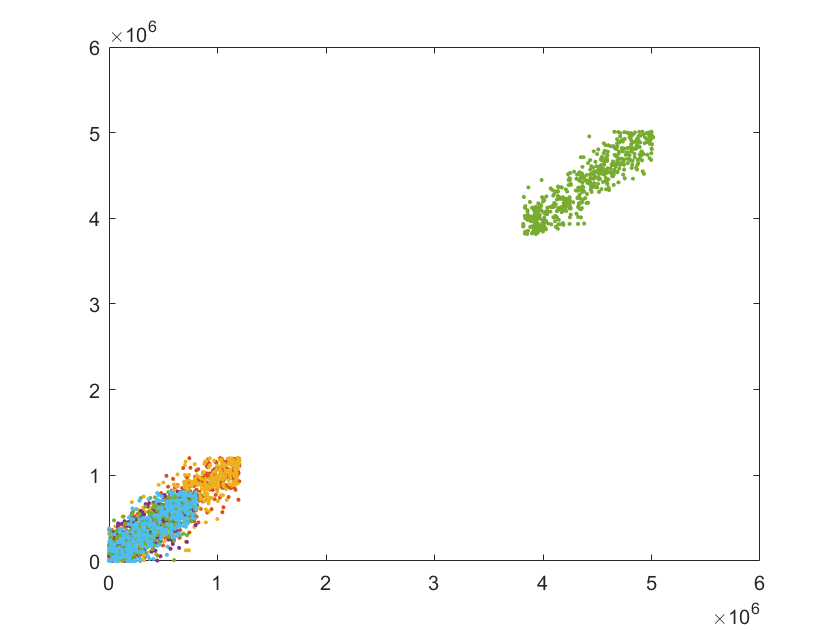

plot(Xtrain(idx(:,1),:),Xtrain(idx(:,2),:),'.')

x=zscore(a(:,1:27));
y=categorical(HCV_stage>2);
[Xtrain,Ytrain,Xtest,Ytest]=trainTestSplit(x,y,0.6);
Mdl=createns(Xtrain)

Mdl =   ExhaustiveSearcher with properties:

         Distance: 'euclidean'
    DistParameter: []
                X: [829×27 double]


idx=knnsearch(Mdl,Xtest,'K',2)

idx =    342   689
   118   199
   461   782
   443   776
   468   667
   541   491
   653   732
   164    30
   671   471
   612   399


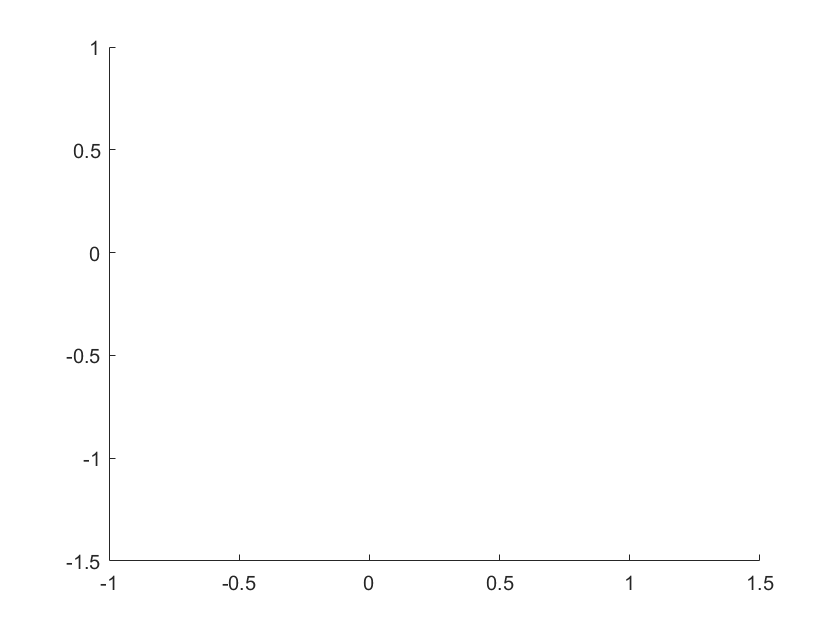

Error using plot
Invalid color value.

Error in internal.stats.scatterplot (line 60)
           h(j,k) = plot(x(ni,k),y(ni,k), ...

Error in gscatter (line 143)
hh = internal.stats.scatterplot(ax, x, y, g ,clr ,sym, siz);

gscatter(Xtrain(idx(:,1),:),Xtrain(idx(:,2),:),Xtest,'rkb')